# PHASE 1 — Load & Visualize BrainWeb Dataset

clear; clc; close all;

% Set Paths
dataDir = fullfile('.', 'data', 'raw');     
outDir  = fullfile('.', 'results', 'figures', 'phase1');

if ~exist(outDir, 'dir')
    mkdir(outDir);
end

% Filenames
files = {
    't1_icbm_normal_1mm_pn0_rf0.nii'
    't1_icbm_normal_1mm_pn3_rf0.nii'
    't1_icbm_normal_1mm_pn5_rf0.nii'
    't1_icbm_normal_1mm_pn9_rf0.nii'
};

labels = {'pn0', 'pn3', 'pn5', 'pn9'};

Loading t1_icbm_normal_1mm_pn0_rf0.nii...


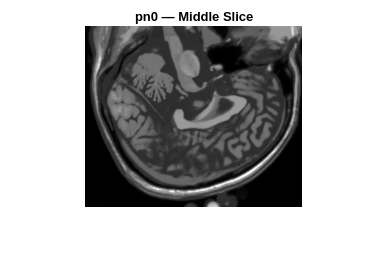

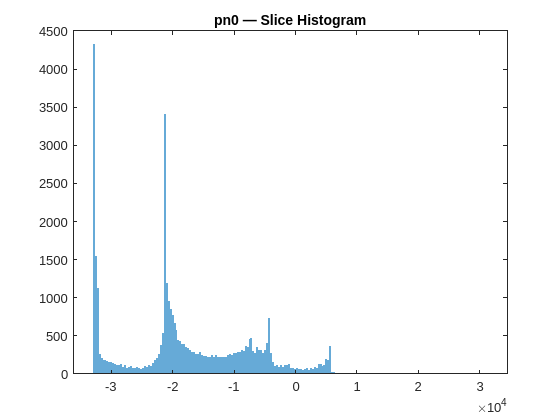

Loading t1_icbm_normal_1mm_pn3_rf0.nii...


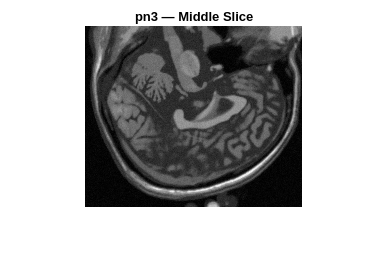

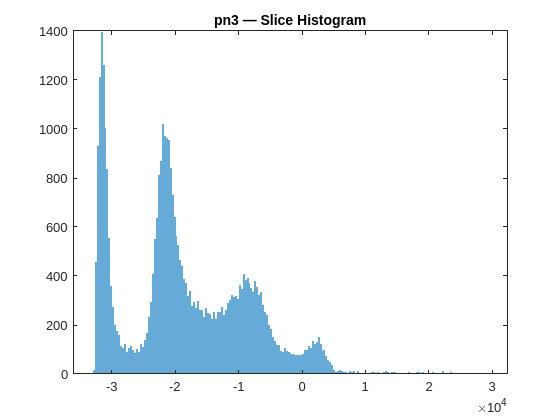

Loading t1_icbm_normal_1mm_pn5_rf0.nii...


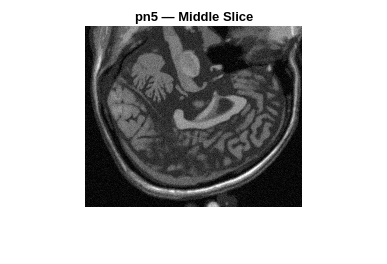

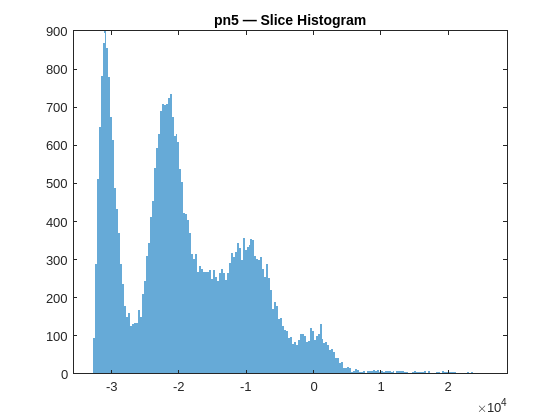

Loading t1_icbm_normal_1mm_pn9_rf0.nii...


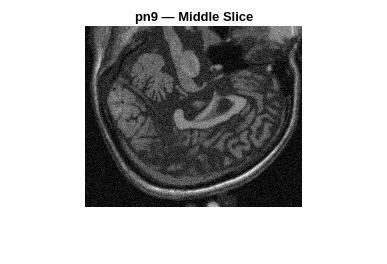

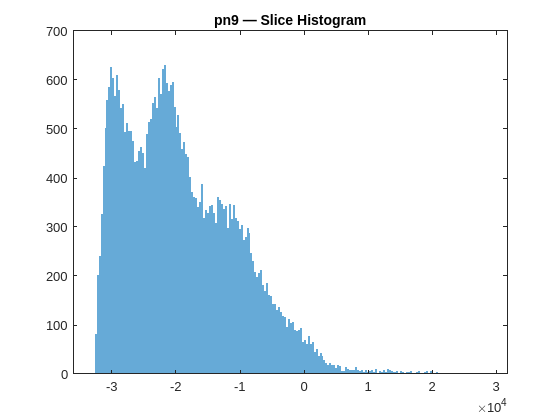

% Loop through each volume
for i = 1:length(files)
    
    fname = files{i};
    label = labels{i};

    fprintf("Loading %s...\n", fname);

    % Load NIfTI volume
    vol = niftiread(fullfile(dataDir, fname));
    vol = double(vol);

    % Extract middle slice
    slice_idx = round(size(vol, 3) / 2);
    slice2d = vol(:,:,slice_idx);

    % Display slice
    figure; 
    imshow(slice2d, []); 
    title([label ' — Middle Slice']);
    saveas(gcf, fullfile(outDir, [label '_slice.png']));

    % Histogram of slice
    figure; 
    histogram(slice2d(:), 200, 'EdgeColor','none');
    title([label ' — Slice Histogram']);
    saveas(gcf, fullfile(outDir, [label '_slice_hist.png']));

end


disp("Phase 1 complete. Outputs saved in results/phase1/");

Phase 1 complete. Outputs saved in results/phase1/
